# **Synchronous Motor Calculator**

**USE IT AT YOUR OWN RISK !!!!!!!**

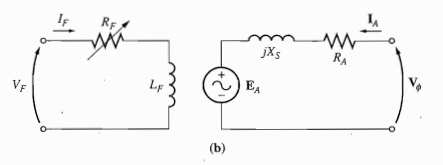

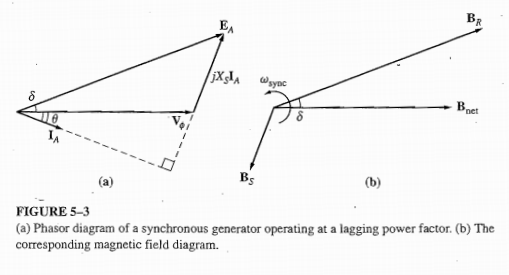

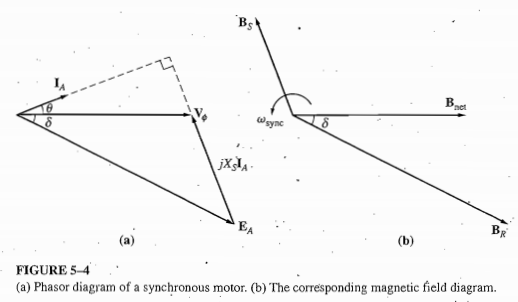

**Parameters:**

V=480 

V = 480

Vphi=V/sqrt(3) 

Vphi = 277.1281

Ra=0;
Xs=10;
P=14051;
pf=1;

**Calculation (Wye Connected) :**

**(ÖRNEK SORU) **

%WYE BAĞLANIRKEN Vfz-nötr = Vfaz-faz/sqrt(3) Olur. 
Iamag=P/(sqrt(3)*V*pf)

Iamag = 16.9007

Iadeg=rad2deg(acos(0.65)) %Güç Faktörünün yönüne göre işaret düşmeyi unutma.

Iadeg = 49.4584

Iadeg=-Iadeg %

Iadeg = -49.4584

Ia=(Iamag*cos(deg2rad(Iadeg)))+(Iamag*sin(deg2rad(Iadeg)))*j

Ia = 10.9855 - 12.8434i

Ea=Vphi+j*Xs*Ia % GÜÇ FAKTÖRÜ GERİDEYSE "+", GERİDEYSE"-" OLACAK.

Ea = 4.0556e+02 + 1.0985e+02i

Eamutlak=abs(Ea)

Eamutlak = 420.1774

Eadeg=rad2deg(angle(Ea))

Eadeg = 15.1560

**Calculation (Delta Connected) :**

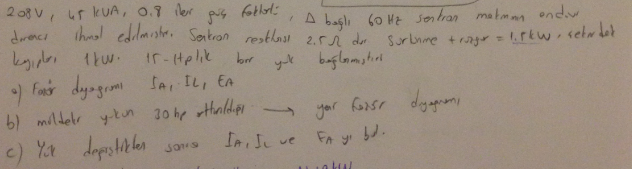

**(ÖRNEK SORU) **

% DELTA BAĞLANIRKEN Vfaz-nötr = Vfaz-faz Olur. Formüllerden doğrudan "V"
% yazılmasının sebebi budur.

% Ilmag=P/(sqrt(3)*V*pf)
% Ildeg=rad2deg(acos(pf)) %Güç Faktörünün yönüne göre işaret düşmeyi unutma.
% Ildeg=Ildeg 
% Il=(Ilmag*cos(deg2rad(Ildeg)))+(Ilmag*sin(deg2rad(Ildeg)))*j
% Ia=Il/sqrt(3)
% Ea=V-j*Xs*Ia % GÜÇ FAKTÖRÜ GERİDEYSE "+", GERİDEYSE"-" OLACAK.
% Eamutlak=abs(Ea)
% Eadeg=rad2deg(angle(Ea))

**Torque-Power Calculations**

f=50;
Pole=4;
nm=(120*f)/Pole

nm = 1500

wm=(2*pi*nm)/60

wm = 157.0796


% WYE BAĞLANTI İÇİN
Tind=(3*Vphi*abs(Ea)*sin(angle(Ea)))/(wm*Xs)

Tind = 58.1434

Tmax=(3*Vphi*abs(Ea))/(wm*Xs)

Tmax = 222.3897

P=(3*Vphi*abs(Ea)*sin(angle(Ea)))/(Xs)

P = 9.1331e+03

Pmax=(3*Vphi*abs(Ea))/(Xs) 

Pmax = 3.4933e+04


%DELTA BAĞLANTI İÇİN
% Tind=(3*V*abs(Ea)*sin(angle(Ea)))/(wm*Xs)
% Tmax=(3*V*abs(Ea))/(wm*Xs)
% P=(3*V*abs(Ea)*sin(angle(Ea)))/(Xs)
% Pmax=(3*V*abs(Ea))/(Xs) 



**Üçgen yıldıza göre kod satırlarını COMMENT yap. Kodlardaki açıklama satırlarını KESİNLİKLE oku. **